## Regresión Lineal de NDVI del año 2022, cuenca del Río Pánuco

### 1.- Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok


Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

Creando área de estudio!!!


Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

Dibujar mapa de prueba de lectura de datos

% if debug_dibujar_mapa == true
%     ndvi(area_estudio==false)=NaN;
%     m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI TEST",[],ndvi_colormap,"NDVI");
%     m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")
%     pause(debug_pausa);
% end 

### 2.- Filtrado de la información

Consultar las imágenes del año 2022

Con la función FIND de Matlab se realizan las consultas de la tabla


tmp = find(  info_hdf.anio >= 2000 & info_hdf.mes == 8 );
info_consulta = info_hdf(tmp,:);

[filas,~] = size(info_consulta);
disp("Num de imágenes: "+filas);

Num de imágenes: 46


### 3.- Recuperar la información y crear las matrices de 3 dimensiones

Declaración de los arreglos que se ocuparan para obtener la información

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 2d para el promedio por día
arr_promedio_dia = zeros(1,filas);

% arreglo 2d para el std por día
arr_desv_est_dia = zeros(1,filas);

Recuperar  la información

for i=1:filas
    disp("Obteniendo información:  "+i+" de "+filas);
    [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(area_estudio==false)=NaN;
    disponibilidad(area_estudio==false)=NaN;

    %quitar las nubes y nieve y demas pixeles anomalos
    ndvi (disponibilidad ~= 0 & disponibilidad ~= 1)=NaN;
    
    %obtener la calidad y almacenarla en el campo correspondiente
    tmp_calidad = m_calidad_imagen(disponibilidad,calidad_total);
    info_consulta.Calidad(i) = tmp_calidad

    if (tmp_calidad >= 95)
        % promedio ndvi 
        arr_promedio_dia(i) = mean(ndvi,'all','omitnan');
        arr_desv_est_dia (i) = std(ndvi,0,'all','omitnan');
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,i) = ndvi;
    else
        % promedio ndvi 
        arr_promedio_dia(i) = nan;
        arr_desv_est_dia(i) = nan;
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,i) = nan;
    end

    % si se desea, mostrar cada imagen individual
    if debug_dibujar_mapa == true 
        m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,i+": NDVI ("+tmp_calidad+"%)",[0 1],ndvi_colormap,"NDVI");
        m_dibujar_kml(dir_data,"RH26",1,'b',"RH26");
        pause(debug_pausa);
    end
end

Obteniendo información:  1 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"      94   
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      -1   
     32    225

Obteniendo información:  2 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  3 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  4 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  5 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  6 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  7 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  8 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  9 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  10 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  11 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  12 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  13 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  14 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  15 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  16 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  17 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  18 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  19 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  20 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  21 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  22 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  23 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  24 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  25 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  26 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  27 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  28 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  29 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  30 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  31 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  32 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  33 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  34 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  35 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  36 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  37 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  38 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  39 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  40 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  41 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  42 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  43 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  44 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  45 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

Obteniendo información:  46 de 46


info_consulta = 46×9 table
    idx    diaj    dia    mes    estacion    anio                          v6                                                 v7                           Calidad
    ___    ____    ___    ___    ________    ____    _______________________________________________    _______________________________________________    _______

     12    225     12      8        2        2000    "MOD13A2.A2000225.h08v06.061.2020050160736.hdf"    "MOD13A2.A2000225.h08v07.061.2020050161733.hdf"       94  
     13    241     28      8        2        2000    "MOD13A2.A2000241.h08v06.061.2020051012754.hdf"    "MOD13A2.A2000241.h08v07.061.2020051012408.hdf"      100  
     32    225

### 4.- Usar los datos obtenidos 

Mostrar el promedio por día de NDVI 

tmp_dias = table2array(info_consulta(:,["anio" "mes" "dia"] ));
t = datetime(tmp_dias(:,1) ,tmp_dias(:,2),tmp_dias(:,3))

t = 46×1 datetime array
   12-Aug-2000
   28-Aug-2000
   13-Aug-2001
   29-Aug-2001
   13-Aug-2002
   29-Aug-2002
   13-Aug-2003
   29-Aug-2003
   12-Aug-2004
   28-Aug-2004
   13-Aug-2005
   29-Aug-2005
   13-Aug-2006
   29-Aug-2006
   13-Aug-2007
   29-Aug-2007
   12-Aug-2008
   28-Aug-2008
   13-Aug-2009
   29-Aug-2009
   13-Aug-2010
   29-Aug-2010
   13-Aug-2011
   29-Aug-2011
   12-Aug-2012
   28-Aug-2012
   13-Aug-2013
   29-Aug-2013
   13-Aug-2014
   29-Aug-2014


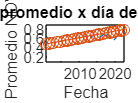


[a0,a1,ajuste] = m_reglin(1:filas,arr_promedio_dia);

plot(t,arr_promedio_dia,t,ajuste,'-o');
%xlim([1 365]);
ylim([0.1 0.9]);
title('NDVI promedio x día del año 2022')
xlabel('Fecha')
ylabel('Promedio NDVI')

Mostrar mapa del promedio por pixel del periodo de estudio 2022

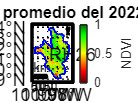

m1 = m_mean_3dpp(arr_ndvi);
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1,"NDVI promedio del 2022",[0 1],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,"b","RH26");

Mostrar mapa de la desviación estandar por pixel del periodo de estudio 2022

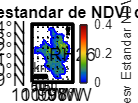

m1std = m_std_3dpp(arr_ndvi);
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1std,"Desviación estandar de NDVI del 2022",[0 0.4], m_colmap('jet'),"Desv Estandar NDVI");
m_dibujar_kml(dir_data,"RH26",1,"b","RH26");

Mostrar mapa del coeficiente de variación por pixel del periodo de estudio 2022

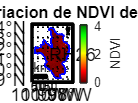

m1cv = m1std./m1;
m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,m1cv,"Coeficiente de variacion de NDVI del 2000 al 2020",[],ndvi_colormap,"NDVI");
m_dibujar_kml(dir_data,"RH26",1,"b","RH26");

Regresión lineal por pixel del periodo de estudio 2022

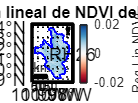


M = arr_ndvi;
tam_arr = size(M);
M = permute(M,[1 3 2]);

ma0 = zeros( tam_arr(1),tam_arr(2));
ma1 = zeros(tam_arr(1),tam_arr(2));

tmp_x = 1:tam_arr(3);

 for i=1:tam_arr(1)
     for j=1:tam_arr(2)
         [ma0(i,j),ma1(i,j),yaj] = m_reglin(tmp_x,M(i,:,j));
     end
 end
 ma1(area_estudio==false)=nan;

 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma1,"Regresión lineal de NDVI del 2022",[-0.02 0.02], flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"b","RH26");